# Notebook 11: Cubic Kernel Detection Simulations

This notebook will be on the simulations that will be used to calculate the probability of detection for signals just like notebook number 9. This will be used to generate data that will be used in the results section of my thesis.

% --Setup
    clear; clc; format compact; close all;
    cd("/home/samkramer/Desktop/Engineering/Thesis Research/MAT Notebooks")

% --Parameters
    num_sims = 500;  % [CHANGE THIS TO CHANGE THE DETECTION RESOLUTION]
    alphas = 70:-0.2:1;
    betas = linspace(0.5, 20, length(alphas));

    W_SNRs = [];
    B_SNRs = [];
    W_detection = [];
    B_detection = [];

% --Simulation loop
    for i = 1:length(alphas)

        % --Loop Setup
            alpha = alphas(i);
            beta = betas(i);
            X_W = [];
            X_B = [];
            W_Det = [];
            B_Det = [];

        for j = 1:num_sims

            % --Create signal and find SNR
                [white_signal, brown_signal, reference, ref_chirp_long, time, W_SNR, B_SNR, denoised_data] = generate_signals(alpha, alpha, beta, beta);

                % --Location of signal start
                    [~, location_start] = findpeaks(denoised_data, "NPeaks",1);

            % --Save SNR values
                X_W = [X_W, W_SNR];
                X_B = [X_B, B_SNR];

            % --Call Kernelized Cross-Correlator
                corr_out_white = kxcorr(white_signal, ref_chirp_long);
                corr_out_white = corr_out_white - min(corr_out_white);
                corr_mean_white = mean(abs(corr_out_white));
                threshold_white = max(corr_out_white) - 1.5*corr_mean_white;

                % --Finding Max
                    [Iw,Jw] = find(corr_out_white == max(corr_out_white));

                corr_out_brown = kxcorr(brown_signal, ref_chirp_long);
                corr_out_brown = corr_out_brown - min(corr_out_brown);
                corr_mean_brown = mean(abs(corr_out_brown));
                threshold_brown = max(corr_out_brown) - 1.5*corr_mean_brown;

                % --Finding Max
                    [Ib,Jb] = find(corr_out_brown == max(corr_out_brown));

            % --Detection criteria for white noise detection
                [peaks, index] = findpeaks(corr_out_white, 'MinPeakHeight', threshold_white, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);

                if abs(peak(2,J) - location_start) <= 1000
                    WD = 1;
                else
                    WD = 0;
                end

            % --Detection criteria for brown noise detection
                [peaks, index] = findpeaks(corr_out_brown, 'MinPeakHeight', threshold_brown, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);

                if abs(peak(2,J) - location_start) <= 1000
                    BD = 1;
                else
                    BD = 0;
                end

            % --Save Data
                W_Det = [W_Det, WD];
                B_Det = [B_Det, BD];

        end

        % --Average out values
            A = mean(X_W);
            B = mean(X_B);

            W_SNRs = [W_SNRs, A];
            B_SNRs = [B_SNRs, B];

            A = mean(W_Det);
            B = mean(B_Det);

            W_detection = [W_detection, A];
            B_detection = [B_detection, B];

    end

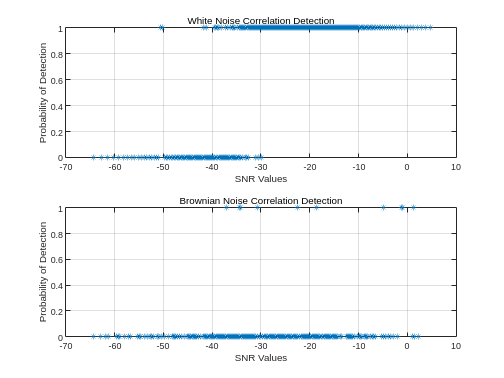

% --Plotting out Detection Data and Saving them
    figure()
    subplot(2,1,1)
    plot(W_SNRs, W_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("White Noise Correlation Detection")

    subplot(2,1,2)
    plot(B_SNRs, B_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("Brownian Noise Correlation Detection")

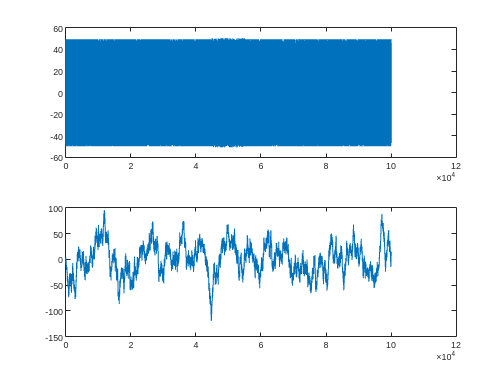

% --Plot out correlation example
    figure()
    subplot(2,1,1)
    plot(white_signal)

    subplot(2,1,2)
    plot(brown_signal)

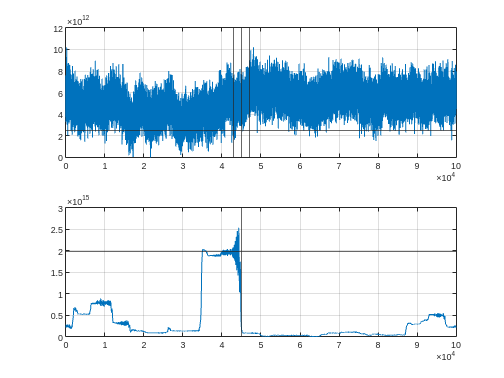

    figure()
    subplot(2,1,1)
    plot(corr_out_white)
        grid on
        hold on
        xlim([0 100000])
        yline(threshold_white)
        xline(location_start)
        xline(location_start + 2000)
        xline(location_start - 2000)

    subplot(2,1,2)
    plot(corr_out_brown)
        hold on
        grid on
        xlim([0 100000])
        yline(threshold_brown)
        xline(location_start)

% --Save Data
    cd("/home/samkramer/Desktop")
    save("Poly50_KCC_Simulation.mat","B_SNRs","B_detection", "W_detection","W_SNRs")

function corr = kxcorr(x, y)

    % --Take Kernels of the signals
        kx = cubic_kernel(x, 50);
        kx_hat = fft(kx);

        ky = cubic_kernel(y, 50);
        ky_hat = fft(ky);

    % --Create correlation output
        corr_hat = kx_hat .* conj(ky_hat);
        corr = ifft(corr_hat);
end

function kf = cubic_kernel(x, n)

    % --Find kernel
        kf = (x + 1).^n;

end